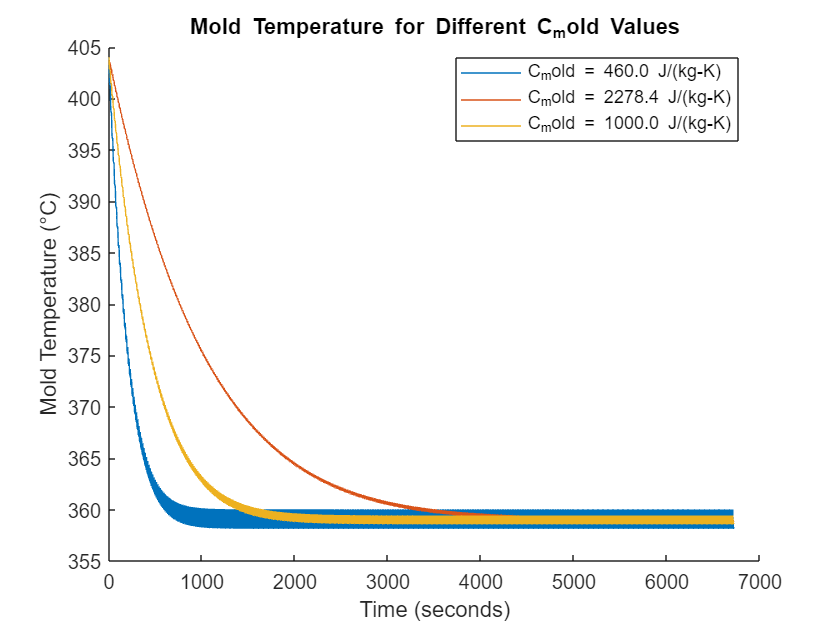

cd('C:\Users\hanib\Desktop\validationSetup\Validation Version 5');

% Physical properties of the gob (unchanged)
c_gob = 1460.0;        % @1100 °C J/(kg-K)
d_gob = 2350.0;        % kg/m^3
v_gob = 9.288814e-05;  % m^3
C_gob = 1 / (c_gob * d_gob * v_gob);

% Define your different scenarios by populating arrays
T_mold_initial_list = [404.001930153661];  % Add more initial mold temperatures as needed
T_gob_initial_list  = [1100];              % Add more gob temperatures as needed
t_cooling_list      = [5.36];              % Cooling times for each scenario
t_settle_list       = [3.12];              % Settle times for each scenario
cycles_list         = [500];               % Number of simulation cycles for each scenario
cooling_start_list  = [0];                 % When the cooling starts for each scenario

% Check that all input lists have the same length
assert(length(T_mold_initial_list) == length(T_gob_initial_list) && ...
       length(T_mold_initial_list) == length(t_cooling_list) && ...
       length(T_mold_initial_list) == length(t_settle_list) && ...
       length(T_mold_initial_list) == length(cycles_list) && ...
       length(T_mold_initial_list) == length(cooling_start_list), ...
       'All input lists must have the same number of scenarios.');

% Predefine parameters that are constant across all scenarios
t_settle_start   = 0.0;   % Settle start time in the cycle
t_cycle          = 13.36; % Total cycle time
t_step           = 0.08;  % Step time for simulation and integration

% Prepare to plot all scenarios in one figure for mold temperature comparison
figure_mold = figure; hold on; % Figure for mold temperature

% Define two different C_mold values for comparison
c_mold_values = [460, 2278.4, 1000]; % J/(kg-K)
d_mold = 7300.0;       % kg/m^3
v_mold = 2.196412e-03; % m^3

% Initialize the legend labels for two distinct C_mold runs
legend_labels = {};

% Loop over each C_mold value for comparison
for c_mold_test = c_mold_values
    % Calculate the C_mold for the current test
    C_mold = 1 / (c_mold_test * d_mold * v_mold);
    
    % Loop over each scenario
    for scenario = 1:length(T_mold_initial_list)
        
        % Extract scenario-specific parameters
        T_mold_initial = T_mold_initial_list(scenario);
        T_gob_initial  = T_gob_initial_list(scenario);
        t_cooling      = t_cooling_list(scenario);
        t_settle       = t_settle_list(scenario);
        cooling_start  = cooling_start_list(scenario);  % Cooling start time
        cycles_to_sim  = cycles_list(scenario);

        % Ensure that the counter blow phase starts after the settle phase ends
        t_counter_start = t_settle_start + t_settle;  % Counter starts after settling
        t_counter_duration = 1.56;  % Duration of counter blow phase

        % Run the simulation for the current scenario
        gob_ts = {};
        mold_ts = {};
        
        % Set initial conditions
        T_mold = T_mold_initial;
        
        for i = 1:cycles_to_sim
            [gob_cycle, mold_cycle] = cycle_simulation(...
                T_gob_initial, T_mold, ...
                t_settle_start, t_settle, ...
                t_counter_start, t_counter_duration, ...
                cooling_start, t_cooling, ...  % Start cooling at "cooling_start" time
                t_cycle, t_step, C_mold, C_gob);
            
            gob_ts = [gob_ts, gob_cycle];
            mold_ts = [mold_ts, mold_cycle];
            T_mold = mold_ts{end};  % Update mold temperature for the next cycle
        end

        % Generate time axis for the plots
        timestamps = (0.0:t_step:(length(mold_ts)-1)*t_step);
        
        % Plot the results for the current scenario (Mold Temperature)
        figure(figure_mold);
        plot(timestamps, cell2mat(mold_ts));

        % Add a label for mold temperature
        legend_labels{end+1} = sprintf('C_mold = %.1f J/(kg-K)', c_mold_test);
    end
end

% Customize the plot for Mold Temperature
figure(figure_mold);
title('Mold Temperature for Different C_mold Values');
xlabel('Time (seconds)');
ylabel('Mold Temperature (°C)');
legend(legend_labels, 'Location', 'Best');
hold off;


%% Function Definitions


function [gob_ts, mold_ts] = cycle_simulation(...
    T_gob_initial, T_mold_initial,...
    t_settle_start, t_settle_duration,...
    t_counter_start, t_counter_duration,...
    cooling_start, t_cooling_duration,...
    cycle_end, t_step, C_mold, C_gob)
% Simulation of one cycle to calculate gob and mold temperatures

    T_gob = T_gob_initial;
    T_mold = T_mold_initial;
    time = 0.0;
    gob_ts = {T_gob_initial};
    mold_ts = {T_mold_initial};

    [a1, a2, b1, b2, ks, kc] = load_coefficients(T_gob_initial, ...
                                                 t_settle_duration, ...
                                                 t_cooling_duration);

    while time < cycle_end

        is_settle = (time >= t_settle_start) & ...
                    (time <  t_settle_start + t_settle_duration);

        is_counter = (time >= t_counter_start) & ...
                     (time <  t_counter_start + t_counter_duration);

        is_cooling = (time >= cooling_start) & ...
                     (time <  cooling_start + t_cooling_duration);

        % Ensure that settle and counter phases do not overlap
        assert(~(is_settle & is_counter), 'Settle and counter phases should not overlap.');

        % Simulate the current step for gob and mold temperature
        [T_gob, T_mold, ~, ~] = cycle_step_simulation(...
            T_gob, T_mold, is_settle, is_counter, ...
            is_cooling, t_step, ...
            a1, a2, b1, b2, ks, kc, C_mold, C_gob);

        gob_ts{end+1} = T_gob;
        mold_ts{end+1} = T_mold;
        time = time + t_step;
    end
end

% Cycle step simulation function
function [T_gob, T_mold, hf_gob, hf_cool] = cycle_step_simulation(...
    T_gob_initial, T_mold_initial,...
    is_settle, is_counter, is_cooling, t_step, ...
    a1, a2, b1, b2, ks, kc, C_mold, C_gob)
% This function simulates a step in the cycle based on the phase

    T_gob = T_gob_initial;
    T_mold = T_mold_initial;
    hf_gob = 0;
    hf_cool = 0;

    assert(~(is_settle & is_counter), 'Settling and counter phases overlap!')

    if is_settle
        [T_gob, T_mold, hf_gob] = ...
           simulate_settle(a1, a2, ks, T_gob, T_mold, t_step, C_mold, C_gob);
    end

    if is_counter
       [T_gob, T_mold, hf_gob] = ...
           simulate_counter(b1, b2, kc, T_gob, T_mold, t_step, C_mold, C_gob);
    end

    if is_cooling
       [T_mold, hf_cool] = simulate_cooling(T_mold, t_step, C_mold);
    end

    if ~is_settle && ~is_counter && ~is_cooling
       T_mold = simulate_passive_cooling(T_mold, t_step, C_mold);
    end
end

% Other supporting functions (simulate_settle, simulate_counter, etc.) remain unchanged

% Other supporting functions remain the same
% Apply coefficients for polynomial fit
function y = apply_cffs(c, x)
    y = c(1) + c(2) * x + c(3) * x^2 + c(4) * x^3;
end

% Settling phase simulation
function [T_g_s, T_m_s, hf_settle] = ...
    simulate_settle(a1, a2, ks, T_g, T_m, t_step, C_mold, C_gob)

    T_g_surface = apply_cffs(a2, T_g - T_m);
    T_m_surface = apply_cffs(a1, T_g - T_m);

    S_settle = 1.011951e-02;  % Surface area of mold-gob interface in settling phase
    hf_settle = S_settle * apply_cffs(ks, T_g_surface - T_m_surface);

    T_m_s = T_m - (hf_settle * C_mold * t_step);
    T_g_s = T_g + (hf_settle * C_gob  * t_step);
end

% Counter blow phase simulation
function [T_g_c, T_m_c, hf_counter] = ...
    simulate_counter(b1, b2, kc, T_g, T_m, t_step, C_mold, C_gob)

    S_counter = 1.504496e-02; % Surface area of gob-mold interface in counter blow phase
    T_g_surface = apply_cffs(b2, T_g - T_m);
    T_m_surface = apply_cffs(b1, T_g - T_m);

    hf_counter = S_counter * apply_cffs(kc, T_g_surface - T_m_surface);

    T_m_c = T_m - (hf_counter * C_mold * t_step);
    T_g_c = T_g + (hf_counter * C_gob  * t_step);
end

% Cooling phase simulation
function [T_m_c, hf_cooling] = simulate_cooling(T_m, t_step, C_mold)

    T_air = 70; % Ambient air temperature
    S_aria = 7.932558e-02; % Surface area exposed to air for cooling
    hf_cooling = S_aria * 360 * (T_air - T_m); % Heat flux for cooling

    T_m_c = T_m + (hf_cooling * C_mold * t_step);
end

% Passive cooling simulation
function T_m_c = simulate_passive_cooling(T_m, t_step, C_mold)

    T_air = 70; % Ambient air temperature

    % Get passive cooling using regression (assuming experiments were at T_air = 50°C)
    hf_passive = (T_m - T_air) * 1.053 - 40.99;

    T_m_c = T_m - (hf_passive * C_mold * t_step);
end

% Coefficient loading function
function [a1, a2, b1, b2, ks, kc] = load_coefficients(...
    T_gob, t_settle, t_cooling)
% Function to load or interpolate coefficients

    % This assumes coefficients are already loaded into the workspace, 
    % using the interpolation logic defined in the earlier code.
    
    interpolation; % Call the interpolation script or function

    a1 = [ alfa1_i{1}(T_gob, t_settle, t_cooling), ...
           alfa1_i{2}(T_gob, t_settle, t_cooling), ...
           alfa1_i{3}(T_gob, t_settle, t_cooling), ...
           alfa1_i{4}(T_gob, t_settle, t_cooling) ];
           
    a2 = [ alfa2_i{1}(T_gob, t_settle, t_cooling), ...
           alfa2_i{2}(T_gob, t_settle, t_cooling), ...
           alfa2_i{3}(T_gob, t_settle, t_cooling), ...
           alfa2_i{4}(T_gob, t_settle, t_cooling) ];
           
    b1 = [ beta1_i{1}(T_gob, t_settle, t_cooling), ...
           beta1_i{2}(T_gob, t_settle, t_cooling), ...
           beta1_i{3}(T_gob, t_settle, t_cooling), ...
           beta1_i{4}(T_gob, t_settle, t_cooling) ];
           
    b2 = [ beta2_i{1}(T_gob, t_settle, t_cooling), ...
           beta2_i{2}(T_gob, t_settle, t_cooling), ...
           beta2_i{3}(T_gob, t_settle, t_cooling), ...
           beta2_i{4}(T_gob, t_settle, t_cooling) ];
           
    ks = [ k_settle_i{1}(T_gob, t_settle, t_cooling), ...
           k_settle_i{2}(T_gob, t_settle, t_cooling), ...
           k_settle_i{3}(T_gob, t_settle, t_cooling), ...
           k_settle_i{4}(T_gob, t_settle, t_cooling) ];
           
    kc = [ k_counter_i{1}(T_gob, t_settle, t_cooling), ...
           k_counter_i{2}(T_gob, t_settle, t_cooling), ...
           k_counter_i{3}(T_gob, t_settle, t_cooling), ...
           k_counter_i{4}(T_gob, t_settle, t_cooling) ];
end

% Interpolation function (previously defined)
function tl = get_param_tl(param)
    TEMPERATURES  = [ 1100.0, 1150.0, 1200.0 ];
    SETTLE_TIMES  = [ 1.52, 1.92, 2.32, 2.72, 3.12 ];
    COOLING_TIMES = [ 3.60, 4.00, 4.48, 4.88, 5.36  ];
    tmp = zeros(length(TEMPERATURES), ...
                length(SETTLE_TIMES), ...
                length(COOLING_TIMES));
    for i = 1:length(TEMPERATURES)
        for j = 1:length(SETTLE_TIMES)
            for k = 1:length(COOLING_TIMES)
                idx = (i - 1) * 25 + (5 - (j - 1) - 1) * 5 + 5 - (k - 1);
                tmp(i, j, k) = param(idx);
            end
        end
    end
    tl = griddedInterpolant({ TEMPERATURES, SETTLE_TIMES, COOLING_TIMES }, ...
                            tmp, 'linear');
end


